clc
clear all
format long g
% Template for assignment 1, advanced part
% ----------------------------------------------
% INPUTS
% ------

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%55
NELEM = 20 ;  % Number of elements
nsteps = 20 ;  % Number of steps
stepsPOST = [1:5:nsteps]; % Steps to post-process

A0 = 1e-2; %m  % Reference AREA
E0 = 10 ; % MPa  % Reference Young's Modulus
sigma_0 = 1; %MPa  % Saturation stress
L = 1 ;%m    % Length of the beam
T = 1; % s Final time
um = 0.2*L; %m   % Maximum displacement
AreaFUN = @(x) (A0*(1+2*(x/L).*(x/L-1)))  ;  % Area as a function of the distance from the left end
stressFUN = @(strain) (sigma_0*(1-exp(-E0/sigma_0*strain))) ;  % Constitutive equation (stress versus strain)
DerStressFUN = @(strain) (E0*exp(-E0/sigma_0*strain)) ;  % Tangent modulus (Derivative of the stress with respect to the strain)
r = [1,NELEM+1]  ; % Indexes Prescribed DOF  %
uEND = @(t) (t/T*um);  %  Non-zero prescribed displacement, as a function of time
TOL_residual = 1e-6;  % Convergence tolerance for the Newton-Raphson
MAXITER = 50 ;  % Maximum number of iterations  for the Newton-Raphson
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% END INPUTS % ------------------------------------------
% MESH INFORMATION
nnode = NELEM+1 ;
COOR = linspace(0,L,nnode)' ;
CN = [(1:(nnode-1))',(2:nnode)'] ;
l = setdiff([1:nnode],r) ;

d = zeros(nnode,1) ;  % Displacement at time tn

TIMES = linspace(0,T,nsteps) ;

% STORE INFORMATION for post-processing purpose
% -----------------------
STRESS_GLO = zeros(NELEM,nsteps) ;
STRAIN_GLO  = zeros(NELEM,nsteps) ;
d_GLO  = zeros(nnode,length(stepsPOST)) ;

iplot = 1;



for istep=1:nsteps
    t = TIMES(istep) ;  % Time
    d(nnode) = uEND(t) ;    
    
    disp(['Number of  step = ',num2str(istep), ', Time = ',num2str(t),', uEND =  ',num2str( uEND(t)) ])
    disp('********************************************************************')
    % Boundary conditions
    %-------------------
    % Compute the vector of internal forces = residual
    % as a function of the nodal displacement n
    
    % Solution of the equations Residual(d) = 0     via Newton-Raphson
    % algoritm
    d_k = d; %   nodal displacements at iteration k
    k = 0 ; % Number of iteration
    while  k <= MAXITER
        % ASsembly the residual vector (= internal forces)
        disp('YOU MUST PROGRAM FUNCTION AssemblyFint...')
        [Residual,STRAIN,STRESS] = AssemblyFint(COOR,CN,d_k,stressFUN,AreaFUN) ;
        normRESIDUAL = norm(Residual(l)) ; % Euclidean norm residual
        disp(['k = ',num2str(k),' res=',num2str(normRESIDUAL),', MAX strain = ',num2str(max(STRAIN)),', MAX stress = ',num2str(max(STRESS))])
        if normRESIDUAL < TOL_residual
            % Convergence
            d = d_k ;
            break
        end
        % The norm of the residual is greater than the prescribed
        % tolerance.  This means that equilibrium is not met
        % Let us calculate the new displacement vector
        
        % Compute the Jacobian of the system of equations
         disp('YOU MUST PROGRAM FUNCTION AssemblyKnon...')
        K = AssemblyKnon(COOR,CN,d_k,AreaFUN,DerStressFUN);
            Delta_d_l = -K(l,l)\Residual(l) ;
        d_k(l) = d_k(l) + Delta_d_l;
        k = k +1 ;
    end
    
    if  k >  MAXITER
        error('The Newtown-R. algorithm has failed to converge')
    else
        d=d_k ;
        d_GLO(:,iplot) = d ;
        STRAIN_GLO(:,iplot) = STRAIN ;
        STRESS_GLO(:,iplot) = STRESS ;
        iplot = iplot +1 ;
    end
end

Number of  step = 1, Time = 0, uEND =  0


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0, MAX strain = 0, MAX stress = 0


Number of  step = 2, Time = 0.052632, uEND =  0.010526


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0083537, MAX strain = 0.21053, MAX stress = 0.87819


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.30996, MAX strain = 0.036876, MAX stress = 0.30841


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.11179, MAX strain = 0.031365, MAX stress = 0.26923


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.038926, MAX strain = 0.024868, MAX stress = 0.22017


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.012263, MAX strain = 0.019293, MAX stress = 0.17546


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0029126, MAX strain = 0.015384, MAX stress = 0.14259


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00031816, MAX strain = 0.01376, MAX stress = 0.12855


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=5.1049e-06, MAX strain = 0.013536, MAX stress = 0.1266


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=1.3707e-09, MAX strain = 0.013533, MAX stress = 0.12657


Number of  step = 3, Time = 0.10526, uEND =  0.021053


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0077966, MAX strain = 0.21743, MAX stress = 0.88631


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.30512, MAX strain = 0.051648, MAX stress = 0.40339


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.11015, MAX strain = 0.046119, MAX stress = 0.36947


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.038458, MAX strain = 0.039392, MAX stress = 0.32559


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.012212, MAX strain = 0.0336, MAX stress = 0.28538


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0029671, MAX strain = 0.029477, MAX stress = 0.2553


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00034458, MAX strain = 0.027698, MAX stress = 0.24193


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=6.3732e-06, MAX strain = 0.027434, MAX stress = 0.23993


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=2.2887e-09, MAX strain = 0.027429, MAX stress = 0.23989


Number of  step = 4, Time = 0.15789, uEND =  0.031579


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0072978, MAX strain = 0.22404, MAX stress = 0.89358


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.30227, MAX strain = 0.066947, MAX stress = 0.48802


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.10922, MAX strain = 0.061407, MAX stress = 0.45886


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.038242, MAX strain = 0.054417, MAX stress = 0.41967


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.012241, MAX strain = 0.04838, MAX stress = 0.38356


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0030429, MAX strain = 0.044016, MAX stress = 0.35607


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00037604, MAX strain = 0.04206, MAX stress = 0.34334


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=8.0439e-06, MAX strain = 0.041745, MAX stress = 0.34128


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=3.894e-09, MAX strain = 0.041738, MAX stress = 0.34123


Number of  step = 5, Time = 0.21053, uEND =  0.042105


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0068517, MAX strain = 0.23035, MAX stress = 0.90009


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.30142, MAX strain = 0.082847, MAX stress = 0.56328


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.10902, MAX strain = 0.077307, MAX stress = 0.53841


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.038277, MAX strain = 0.070013, MAX stress = 0.50348


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.012351, MAX strain = 0.063699, MAX stress = 0.47112


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0031413, MAX strain = 0.059063, MAX stress = 0.44602


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00041324, MAX strain = 0.056903, MAX stress = 0.43393


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=1.0248e-05, MAX strain = 0.056526, MAX stress = 0.43179


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=6.7295e-09, MAX strain = 0.056517, MAX stress = 0.43173


Number of  step = 6, Time = 0.26316, uEND =  0.052632


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0064533, MAX strain = 0.23634, MAX stress = 0.9059


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.30257, MAX strain = 0.099436, MAX stress = 0.63004


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.10954, MAX strain = 0.093913, MAX stress = 0.60903


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.038566, MAX strain = 0.086268, MAX stress = 0.57797


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.012543, MAX strain = 0.079637, MAX stress = 0.54904


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0032638, MAX strain = 0.074694, MAX stress = 0.52618


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.000457, MAX strain = 0.072299, MAX stress = 0.5147


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=1.3158e-05, MAX strain = 0.071846, MAX stress = 0.5125


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=1.1771e-08, MAX strain = 0.071832, MAX stress = 0.51243


Number of  step = 7, Time = 0.31579, uEND =  0.063158


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0060981, MAX strain = 0.242, MAX stress = 0.91108


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.30576, MAX strain = 0.11682, MAX stress = 0.68907


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.1108, MAX strain = 0.11134, MAX stress = 0.67155


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.039116, MAX strain = 0.10328, MAX stress = 0.644


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.012822, MAX strain = 0.096289, MAX stress = 0.61821


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.003412, MAX strain = 0.090996, MAX stress = 0.59746


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00050823, MAX strain = 0.08833, MAX stress = 0.58659


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=1.6993e-05, MAX strain = 0.087783, MAX stress = 0.58432


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=2.0758e-08, MAX strain = 0.087763, MAX stress = 0.58423


Number of  step = 8, Time = 0.36842, uEND =  0.073684


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.005782, MAX strain = 0.24732, MAX stress = 0.91569


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.31103, MAX strain = 0.13512, MAX stress = 0.74108


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.11282, MAX strain = 0.12971, MAX stress = 0.72669


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.039934, MAX strain = 0.12118, MAX stress = 0.70234


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.013191, MAX strain = 0.11377, MAX stress = 0.67944


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0035881, MAX strain = 0.10808, MAX stress = 0.66066


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00056794, MAX strain = 0.1051, MAX stress = 0.6504


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=2.2031e-05, MAX strain = 0.10443, MAX stress = 0.64807


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=3.6756e-08, MAX strain = 0.10441, MAX stress = 0.64797


Number of  step = 9, Time = 0.42105, uEND =  0.084211


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0055014, MAX strain = 0.2523, MAX stress = 0.91978


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.31846, MAX strain = 0.1545, MAX stress = 0.78669


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.11562, MAX strain = 0.14922, MAX stress = 0.77511


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.041032, MAX strain = 0.14011, MAX stress = 0.75368


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.013655, MAX strain = 0.13221, MAX stress = 0.73343


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0037942, MAX strain = 0.12606, MAX stress = 0.71652


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00063718, MAX strain = 0.12272, MAX stress = 0.70689


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=2.8617e-05, MAX strain = 0.12191, MAX stress = 0.70451


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=6.5073e-08, MAX strain = 0.12187, MAX stress = 0.70439


Number of  step = 10, Time = 0.47368, uEND =  0.094737


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0052531, MAX strain = 0.25691, MAX stress = 0.9234


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.32814, MAX strain = 0.17515, MAX stress = 0.82648


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.11924, MAX strain = 0.17005, MAX stress = 0.81741


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.042423, MAX strain = 0.16027, MAX stress = 0.79864


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.014219, MAX strain = 0.15179, MAX stress = 0.78084


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0040328, MAX strain = 0.14511, MAX stress = 0.76569


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00071711, MAX strain = 0.14135, MAX stress = 0.7567


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=3.7166e-05, MAX strain = 0.14036, MAX stress = 0.75428


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=1.147e-07, MAX strain = 0.1403, MAX stress = 0.75415


Number of  step = 11, Time = 0.52632, uEND =  0.10526


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0050341, MAX strain = 0.26117, MAX stress = 0.92659


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.34017, MAX strain = 0.19729, MAX stress = 0.86095


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.12371, MAX strain = 0.1925, MAX stress = 0.85412


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.044122, MAX strain = 0.18188, MAX stress = 0.83778


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.01489, MAX strain = 0.17273, MAX stress = 0.82223


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0043066, MAX strain = 0.16542, MAX stress = 0.80875


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00080891, MAX strain = 0.16116, MAX stress = 0.80043


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=4.8168e-05, MAX strain = 0.15995, MAX stress = 0.798


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=2.0046e-07, MAX strain = 0.15987, MAX stress = 0.79783


Number of  step = 12, Time = 0.57895, uEND =  0.11579


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0048417, MAX strain = 0.26507, MAX stress = 0.9294


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.35467, MAX strain = 0.22123, MAX stress = 0.89056


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.12909, MAX strain = 0.21689, MAX stress = 0.8857


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.046145, MAX strain = 0.20526, MAX stress = 0.87159


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.015675, MAX strain = 0.19528, MAX stress = 0.85813


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0046182, MAX strain = 0.18723, MAX stress = 0.84623


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.00091376, MAX strain = 0.18238, MAX stress = 0.83859


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=6.2179e-05, MAX strain = 0.1809, MAX stress = 0.83618


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=3.4599e-07, MAX strain = 0.18078, MAX stress = 0.83599


Number of  step = 13, Time = 0.63158, uEND =  0.12632


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0046738, MAX strain = 0.26859, MAX stress = 0.93184


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.37175, MAX strain = 0.24737, MAX stress = 0.91573


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.13542, MAX strain = 0.2437, MAX stress = 0.91258


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.048509, MAX strain = 0.23079, MAX stress = 0.90053


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.016579, MAX strain = 0.21982, MAX stress = 0.88899


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0049704, MAX strain = 0.21087, MAX stress = 0.8786


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0010328, MAX strain = 0.20532, MAX stress = 0.87167


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=7.9809e-05, MAX strain = 0.20349, MAX stress = 0.8693


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=5.876e-07, MAX strain = 0.20332, MAX stress = 0.86909


Number of  step = 14, Time = 0.68421, uEND =  0.13684


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.004528, MAX strain = 0.27176, MAX stress = 0.93396


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.39153, MAX strain = 0.27621, MAX stress = 0.93684


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.14272, MAX strain = 0.27357, MAX stress = 0.93515


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.051231, MAX strain = 0.25901, MAX stress = 0.92499


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.01761, MAX strain = 0.2468, MAX stress = 0.91525


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0053658, MAX strain = 0.23675, MAX stress = 0.90628


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0011672, MAX strain = 0.23034, MAX stress = 0.90008


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=0.00010169, MAX strain = 0.22808, MAX stress = 0.8978


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=9.7866e-07, MAX strain = 0.22785, MAX stress = 0.89756


Number of  step = 15, Time = 0.73684, uEND =  0.14737


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0044027, MAX strain = 0.27455, MAX stress = 0.93579


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.4141, MAX strain = 0.30844, MAX stress = 0.95424


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.15106, MAX strain = 0.30736, MAX stress = 0.95375


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.054323, MAX strain = 0.29067, MAX stress = 0.94534


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.018772, MAX strain = 0.27687, MAX stress = 0.93726


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0058064, MAX strain = 0.26543, MAX stress = 0.92965


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0013178, MAX strain = 0.25797, MAX stress = 0.9242


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=0.00012846, MAX strain = 0.25516, MAX stress = 0.92204


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=1.5938e-06, MAX strain = 0.25483, MAX stress = 0.92178


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 9 res=2.5353e-10, MAX strain = 0.25482, MAX stress = 0.92178


Number of  step = 16, Time = 0.78947, uEND =  0.15789


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0042962, MAX strain = 0.27703, MAX stress = 0.93735


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.44039, MAX strain = 0.34505, MAX stress = 0.96827


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.16075, MAX strain = 0.34639, MAX stress = 0.96869


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.057911, MAX strain = 0.32682, MAX stress = 0.96192


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.020111, MAX strain = 0.31095, MAX stress = 0.95538


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0063093, MAX strain = 0.29772, MAX stress = 0.94907


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0014901, MAX strain = 0.28891, MAX stress = 0.94437


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=0.0001616, MAX strain = 0.28538, MAX stress = 0.94238


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=2.5602e-06, MAX strain = 0.28491, MAX stress = 0.9421


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 9 res=6.7015e-10, MAX strain = 0.2849, MAX stress = 0.9421


Number of  step = 17, Time = 0.84211, uEND =  0.16842


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0042067, MAX strain = 0.2849, MAX stress = 0.9421


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.46934, MAX strain = 0.38738, MAX stress = 0.97922


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.17142, MAX strain = 0.39246, MAX stress = 0.98025


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.061854, MAX strain = 0.36894, MAX stress = 0.97501


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.021578, MAX strain = 0.35031, MAX stress = 0.9699


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0068561, MAX strain = 0.33471, MAX stress = 0.96481


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0016786, MAX strain = 0.32414, MAX stress = 0.96089


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=0.0002006, MAX strain = 0.31968, MAX stress = 0.95911


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=3.9835e-06, MAX strain = 0.31901, MAX stress = 0.95883


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 9 res=1.6561e-09, MAX strain = 0.31899, MAX stress = 0.95882


Number of  step = 18, Time = 0.89474, uEND =  0.17895


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0041331, MAX strain = 0.31899, MAX stress = 0.95882


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.50153, MAX strain = 0.43743, MAX stress = 0.9874


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.18327, MAX strain = 0.44827, MAX stress = 0.9887


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.066229, MAX strain = 0.41929, MAX stress = 0.9849


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.023199, MAX strain = 0.39684, MAX stress = 0.9811


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0074573, MAX strain = 0.37801, MAX stress = 0.97718


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0018867, MAX strain = 0.3651, MAX stress = 0.97403


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=0.00024647, MAX strain = 0.35937, MAX stress = 0.9725


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=6.0398e-06, MAX strain = 0.3584, MAX stress = 0.97224


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 9 res=3.8723e-09, MAX strain = 0.35838, MAX stress = 0.97223


Number of  step = 19, Time = 0.94737, uEND =  0.18947


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0040741, MAX strain = 0.35838, MAX stress = 0.97223


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.53702, MAX strain = 0.49814, MAX stress = 0.99314


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.19634, MAX strain = 0.51731, MAX stress = 0.99433


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.071045, MAX strain = 0.48093, MAX stress = 0.99185


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.02498, MAX strain = 0.45323, MAX stress = 0.98924


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0081145, MAX strain = 0.42998, MAX stress = 0.98643


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0021149, MAX strain = 0.41384, MAX stress = 0.98405


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=0.00029964, MAX strain = 0.40636, MAX stress = 0.98281


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=8.9187e-06, MAX strain = 0.40496, MAX stress = 0.98257


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 9 res=8.5576e-09, MAX strain = 0.40492, MAX stress = 0.98256


Number of  step = 20, Time = 1, uEND =  0.2


********************************************************************


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 0 res=0.0040286, MAX strain = 0.40492, MAX stress = 0.98256


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 1 res=0.57577, MAX strain = 0.57366, MAX stress = 0.99677


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 2 res=0.2106, MAX strain = 0.60223, MAX stress = 0.99758


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 3 res=0.076297, MAX strain = 0.55704, MAX stress = 0.99619


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 4 res=0.026917, MAX strain = 0.52273, MAX stress = 0.99463


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 5 res=0.0088269, MAX strain = 0.49369, MAX stress = 0.99282


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 6 res=0.0023628, MAX strain = 0.47318, MAX stress = 0.99119


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 7 res=0.00036028, MAX strain = 0.46327, MAX stress = 0.99027


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 8 res=1.2818e-05, MAX strain = 0.46123, MAX stress = 0.99007


YOU MUST PROGRAM FUNCTION AssemblyKnon...


YOU MUST PROGRAM FUNCTION AssemblyFint...


k = 9 res=1.7854e-08, MAX strain = 0.46115, MAX stress = 0.99006


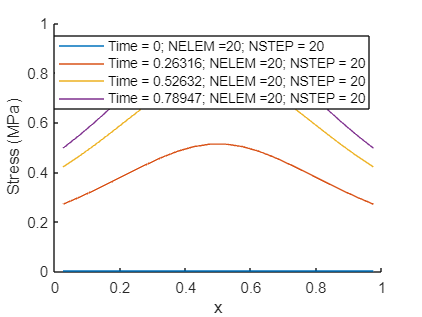




% Evolution of stresses along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Stress (MPa)')
COOR_gauss = (COOR(CN(:,2))+  COOR(CN(:,1)))/2 ;
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR_gauss,STRESS_GLO(:,stepsPOST(i))) ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
end

legend(hplot,LegendPlot)

legend('off')
legend

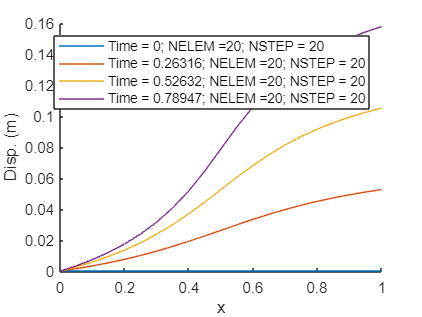


% Evolution of displacements along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Disp. (m)')
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR,d_GLO(:,stepsPOST(i))) ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
end

legend(hplot,LegendPlot)

legend('off')
legend

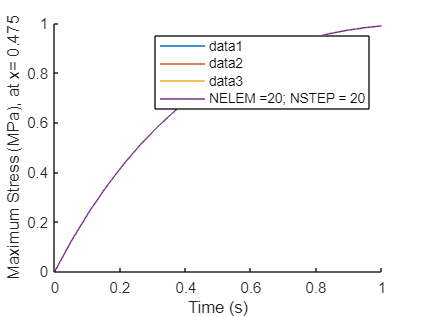




% Location of maximum stress

[stressEND,indELEM ]= max(STRESS_GLO(:,end)) ;
COOR_max_stress= COOR_gauss(indELEM) ;

figure
hold on
xlabel('Time (s)')
ylabel([['Maximum Stress (MPa), at x= ',num2str(COOR_max_stress)]]) ;
for i = 1:nsteps_plot
    h =   plot(TIMES,STRESS_GLO(indELEM,:)) ;
end

legend(h,['NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)])

legend('off')
legend